# **Deep Learning Example: Traning from scratch using CIFAR-10 Dataset**

**Copyright 2017 The MathWorks, Inc.**

**This example** explores creating a convolutional neural network (CNN) from scratch. You will need to download images in order to run this example.

*Please see the file in this directory: ***DownloadCIFAR10.m ***Running this file will help you download CIFAR10 if you choose to use those images.*

**Load training data**

% Please note: these are 4 of the 10 categories available
% Feel free to choose which ever you like best!
categories = {'Deer','Dog','Frog','Cat'};

rootFolder = 'cifar10Train';
imds = imageDatastore(fullfile(rootFolder, categories), ...
    'LabelSource', 'foldernames');

Error using imageDatastore (line 85)
Cannot find files or folders matching: 'cifar10Train\Deer'.

**Define Layers**

Training from scratch gives you a lot of freedom to explore the architecture. Take a look at this architecture and see how you might want to alter it: for example, how would you add another convolutional layer?

varSize = 32;
conv1 = convolution2dLayer(5,varSize,'Padding',2,'BiasLearnRateFactor',2);
conv1.Weights = gpuArray(single(randn([5 5 3 varSize])*0.0001));
fc1 = fullyConnectedLayer(64,'BiasLearnRateFactor',2);
fc1.Weights = gpuArray(single(randn([64 576])*0.1));
fc2 = fullyConnectedLayer(4,'BiasLearnRateFactor',2);
fc2.Weights = gpuArray(single(randn([4 64])*0.1));

layers = [
    imageInputLayer([varSize varSize 3]);
    conv1;
    maxPooling2dLayer(3,'Stride',2);
    reluLayer();
    convolution2dLayer(5,32,'Padding',2,'BiasLearnRateFactor',2, 'WeightLearnRateFactor',2);
    reluLayer();
    convolution2dLayer(5,32,'Padding',2,'BiasLearnRateFactor',2);
    reluLayer();
    averagePooling2dLayer(3,'Stride',2);
    convolution2dLayer(5,64,'Padding',2,'BiasLearnRateFactor',2);
    reluLayer();
    averagePooling2dLayer(3,'Stride',2);
    fc1;
    reluLayer();
    fc2;
    softmaxLayer()
    classificationLayer()];


**Define training options**

The training options is another parameter that can significantly increase or decrease the accuracy of the network. Try altering some of these values and see what happens to the overall accuracy of the network. 

opts = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 8, ...
    'L2Regularization', 0.004, ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 100, ...
    'Verbose', true);


**Train! **

This is where the training happens. This can take a few minutes or longer depending on your hardware. Training on a GPU is recommended.

[net, info] = trainNetwork(imds, layers, opts);

**Load test data**


rootFolder = 'cifar10Test';
imds_test = imageDatastore(fullfile(rootFolder, categories), ...
    'LabelSource', 'foldernames');

**Test one at a time**

Run this section multiple times to get a feel for the random images and how they are being classified. If the title of the image is green, this is a correct prediction. If the title is red, the prediction is incorrect.

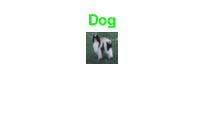

labels = classify(net, imds_test);

ii = randi(4000);
im = imread(imds_test.Files{ii});
imshow(im);
if labels(ii) == imds_test.Labels(ii)
   colorText = 'g'; 
else
    colorText = 'r';
end
title(char(labels(ii)),'Color',colorText);

**Do it all at once**

This section of code will run through all the test data and compare the predicted labels with the actual labels. This will give a feel for how the network is doing overall with one average prediction value.

% This could take a while if you are not using a GPU
confMat = confusionmat(imds_test.Labels, labels);
confMat = confMat./sum(confMat,2);
mean(diag(confMat))

ans = 0.6600